## low pass filtering

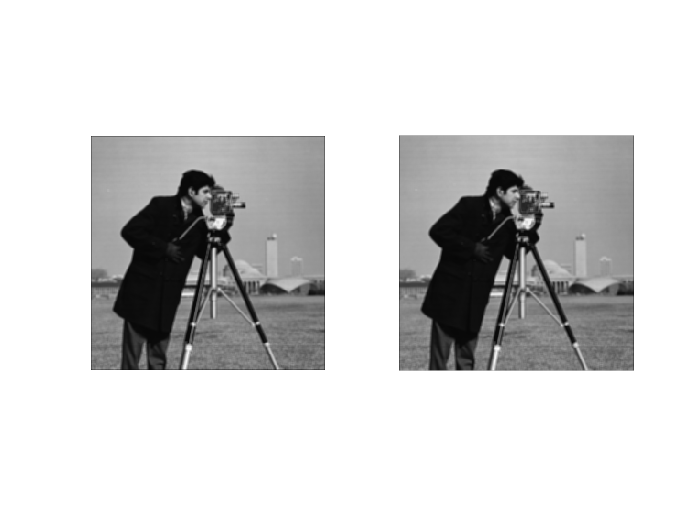

cm = imread('cameraman.tif');

f1 = ones(3, 3)/9;
cm1 = filter2(f1, cm, 'same');
% or
f2 = fspecial("average", [3, 3]);
cm2 = filter2(f2, cm, 'same');

figure;
subplot(1, 2, 1); imshow(cm1/255)
subplot(1, 2, 2); imshow(cm2/255)

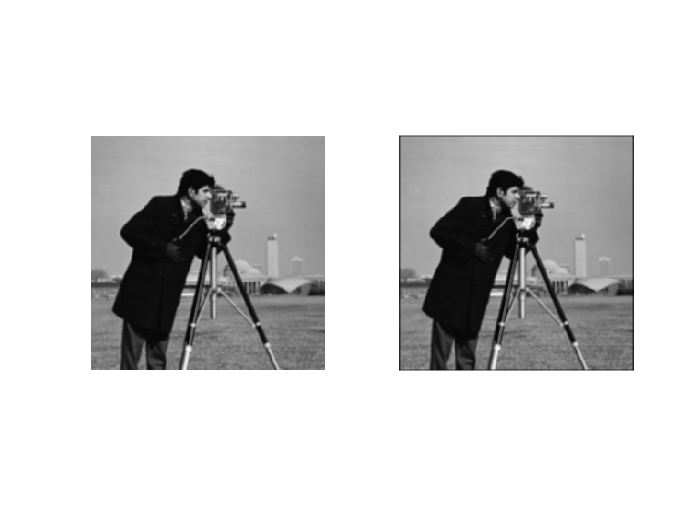

cm21 = filter2(f2, cm, 'valid'); % 254*254
cm22 = filter2(f2, cm, 'full');  % 258*258

figure;
subplot(1, 2, 1); imshow(cm21/255)
subplot(1, 2, 2); imshow(cm22/255)

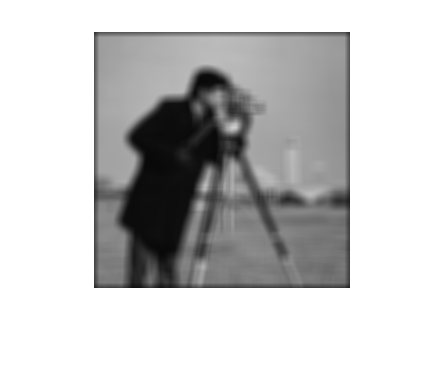

f3 = fspecial('average', 11);
cm3 = filter2(f3, cm, 'same');
figure; imshow(cm3/255)

## gaussian filter & wiener filter

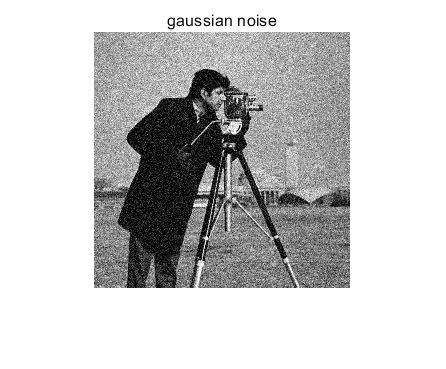

clear; clc;
cm = imread('cameraman.tif');
cm_n = imnoise(cm, 'gaussian', 0.01);
figure; imshow(cm_n);  title('gaussian noise')

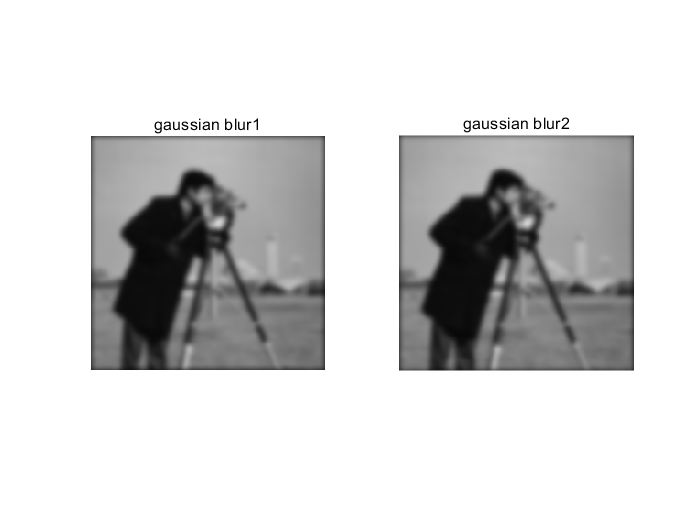

sigma = 3;
cutoff = ceil(3*sigma);
f_gau = fspecial('gaussian', 2*cutoff+1, sigma);  
% this range contains most infos of gaussian distribution

out01 = conv2(cm, f_gau, 'same');
out02 = filter2(f_gau, cm, "same");

figure; 
subplot(1, 2, 1); imshow(out01/255); title('gaussian blur1')
subplot(1, 2, 2); imshow(out02/255); title('gaussian blur2')

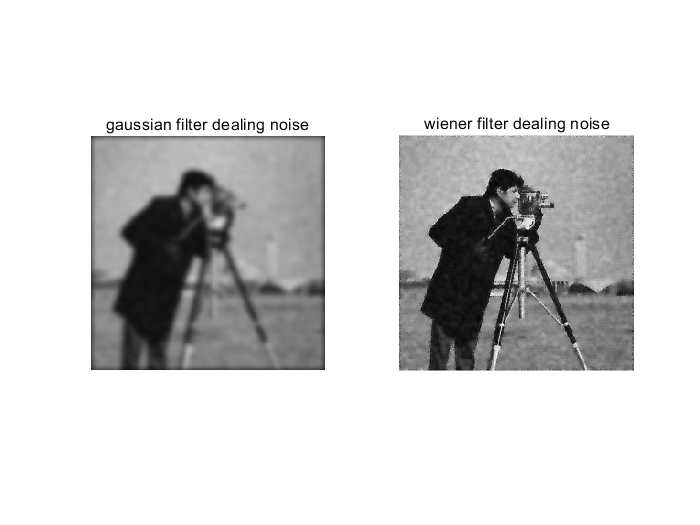

figure;

out1 = conv2(cm_n, f_gau, 'same');
subplot(1, 2, 1); imshow(out1/255); title('gaussian filter dealing noise')

out2 = wiener2(cm_n, [5, 5]);
subplot(1, 2, 2); imshow(out2); title('wiener filter dealing noise')

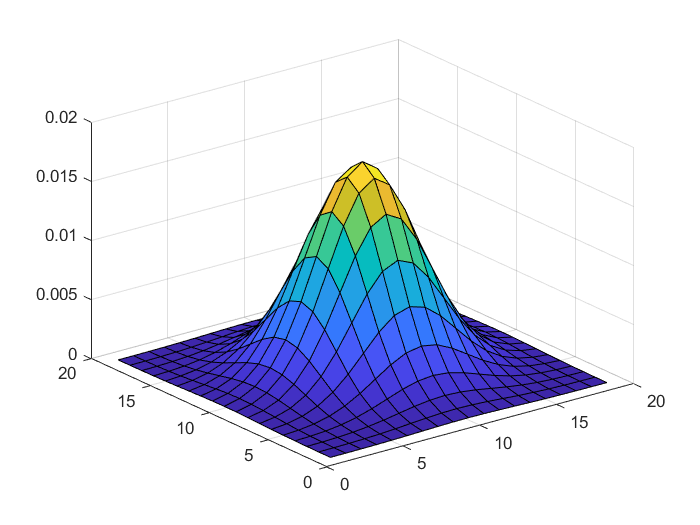

figure; surf(1 : 2*cutoff+1, 1 : 2*cutoff+1, f_gau)

## median filter & average filter & order filter

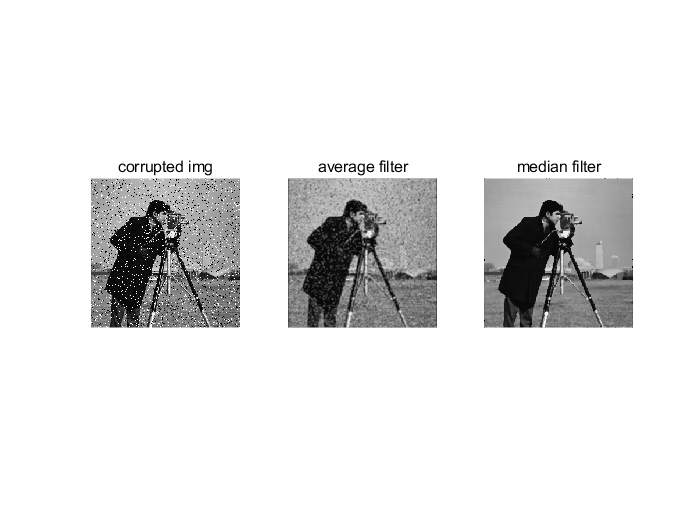

clear; clc;
cm = imread('cameraman.tif');
cm_sp = imnoise(cm, "salt & pepper", 0.1);

f_m = fspecial('average');
cm1 = filter2(f_m, cm_sp);

cm2 = medfilt2(cm_sp); 

figure; 
subplot(1, 3, 1); imshow(cm_sp); title('corrupted img')
subplot(1, 3, 2); imshow(cm1/255); title("average filter")
subplot(1, 3, 3); imshow(cm2); title('median filter')

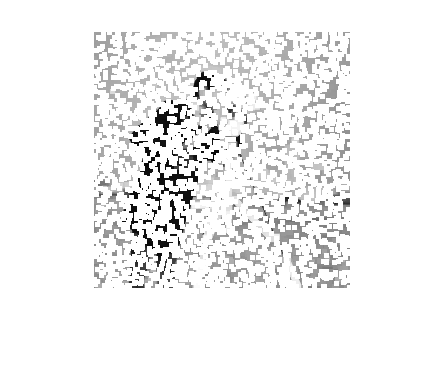

cm3 = ordfilt2(cm_sp, 25, ones(5, 5));
% the 25th num increasingly ordered of 5*5= max of 5*5

figure; imshow(cm3)

## high pass filter (first order derivatives, for edge detection)

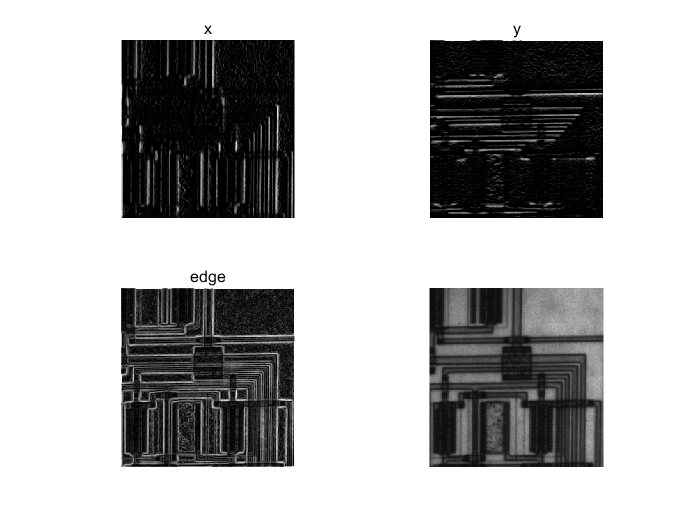

a = imread('circuit.tif');
imshow(a)

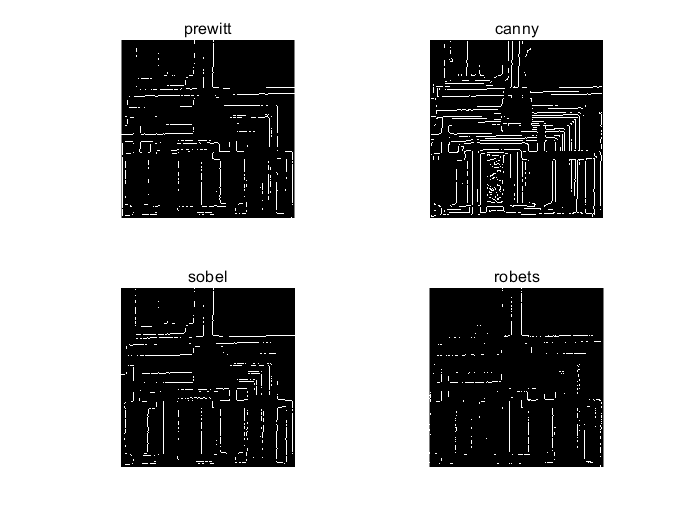


e1 = edge(a, 'prewitt');
e2 = edge(a, "canny");
e3 = edge(a, 'sobel');
e4 = edge(a, 'roberts');

figure;
subplot(2, 2, 1); imshow(e1); title('prewitt')
subplot(2, 2, 2); imshow(e2); title('canny')
subplot(2, 2, 3); imshow(e3); title('sobel')
subplot(2, 2, 4); imshow(e4); title('robets')

handi-kernel prewitt filter

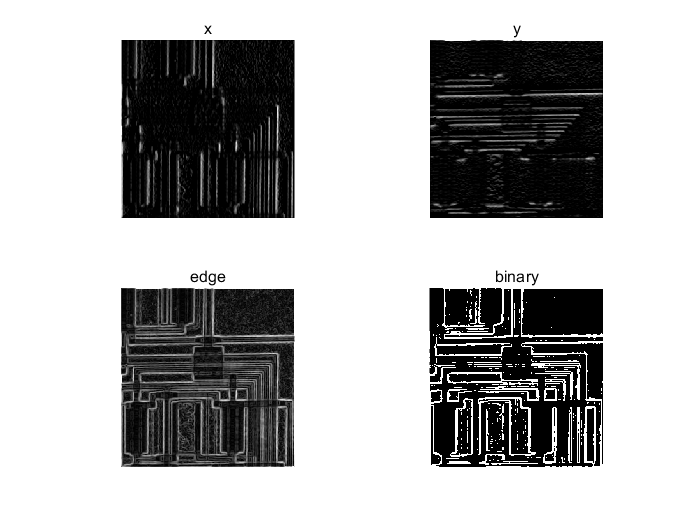

px = [-1 0 1; -1 0 1; -1 0 1];
py = px';
ax = filter2(px, a);
ay = filter2(py, a);
aedge = sqrt(ax.^2 + ay.^2);
aedge_bw = im2bw(uint8(aedge), 0.3);

figure;
subplot(2, 2, 1); imshow(ax/255); title('x')
subplot(2, 2, 2); imshow(ay/255); title('y')
subplot(2, 2, 3); imshow(aedge/255); title('edge')
subplot(2, 2, 4); imshow(aedge_bw); title('binary')

## laplacian filter( 2nd derivatives, for edge detection)

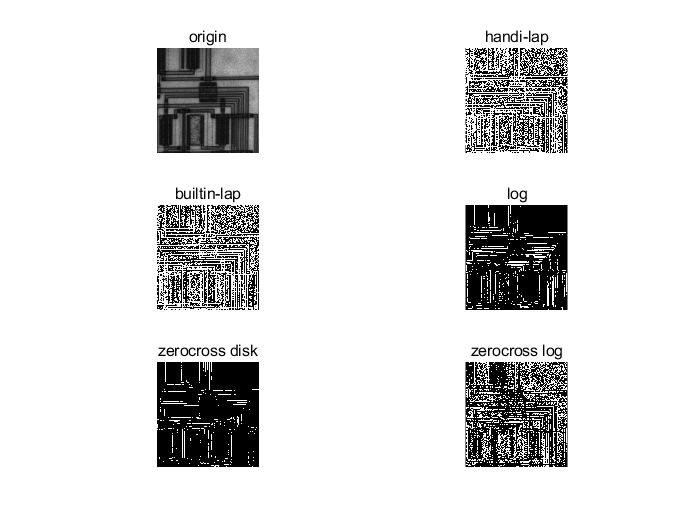

clear; clc;
a = imread('circuit.tif');

f1 = [0 1 0; 1 -4 1; 0 1 0];
a_f1 = conv2(a, f1, 'valid');

f2 = fspecial('laplacian');
a_f2 = filter2(f2, a);

a_e1 = edge(a, 'log');     %laplacian of gaussian

f3 = fspecial('disk');
a_e2 = edge(a, 'zerocross', f3);

f4 = fspecial('log');
a_e3 = edge(a, 'zerocross', f4);

figure;
subplot(3, 2, 1); imshow(a); title('origin')
subplot(3, 2, 2); imshow(a_f1); title('handi-lap')
subplot(3, 2, 3); imshow(a_f2); title('builtin-lap')
subplot(3, 2, 4); imshow(a_e1); title('log')
subplot(3, 2, 5); imshow(a_e2); title('zerocross disk')
subplot(3, 2, 6); imshow(a_e3); title('zerocross log')